# Analysis of Simulations

## Trajectorie

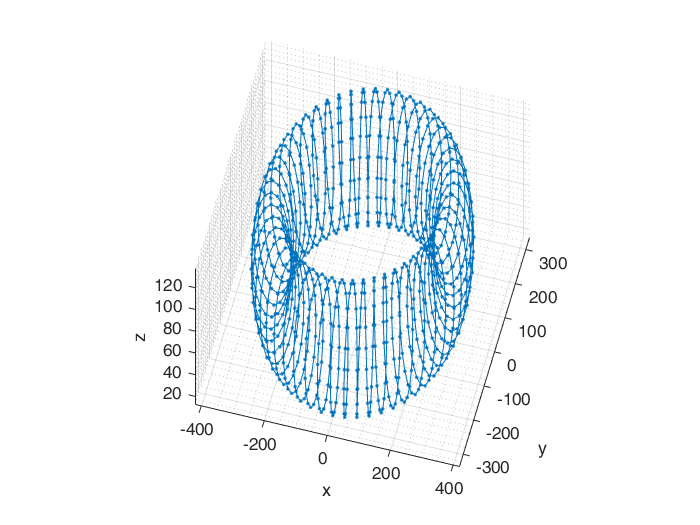

plot3(traj(1,:),traj(2,:),traj(3,:),'Marker','.','LineStyle','-')
xlabel('x');ylabel('y');zlabel('z')
grid on; grid minor;
axis vis3d; view([15 60]);rotate3d on;

## Vergleich Berechnung und Simulation

ticks = struct();
ticks.range = 0:pi/2:2*pi;
ticks.chars = {'0','pi/2','pi','3*pi/2','2*pi'};

### Gesamt

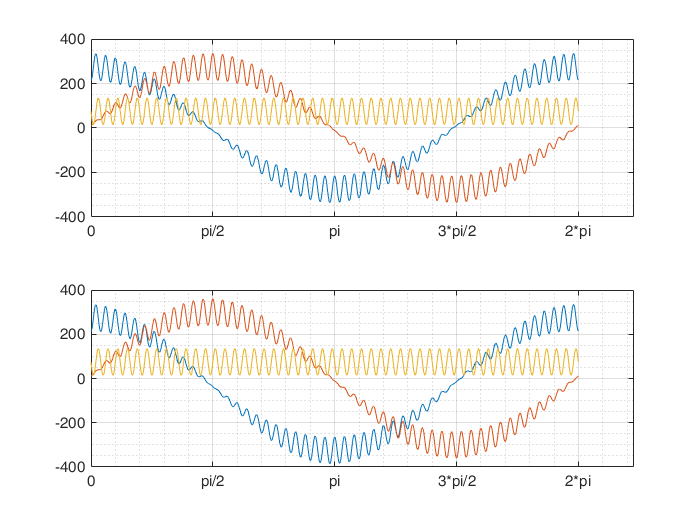

tiledlayout(2,1); nexttile(1);
plot(simAngRS,traj);
setupPlot(ticks);
nexttile(2);
plot(simAngRS,simCordRS)
setupPlot(ticks);

### Vergleich der einzelnen Achsen

#### x-Achse

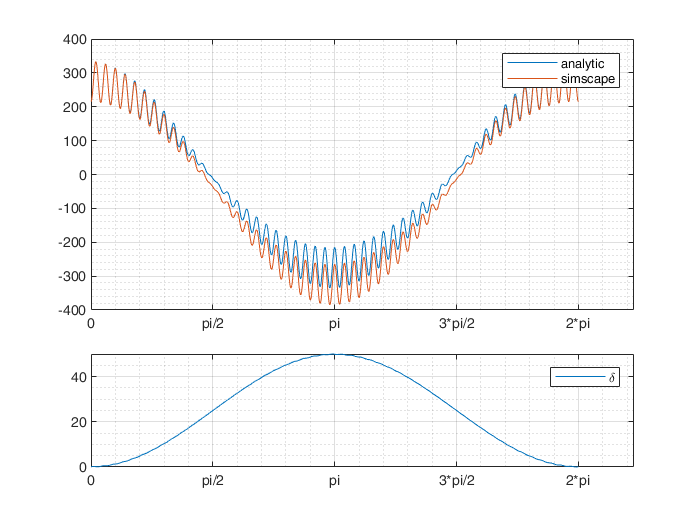

tiledlayout(3,1);
nexttile(1,[2 1]);
plot(simAngRS,[traj(1,:);simCordRS(1,:)])
setupPlot(ticks); legend('analytic','simscape');

nexttile(3);
plot(simAngRS,[traj(1,:)-simCordRS(1,:)])
setupPlot(ticks); legend('\delta');

#### y-Achse

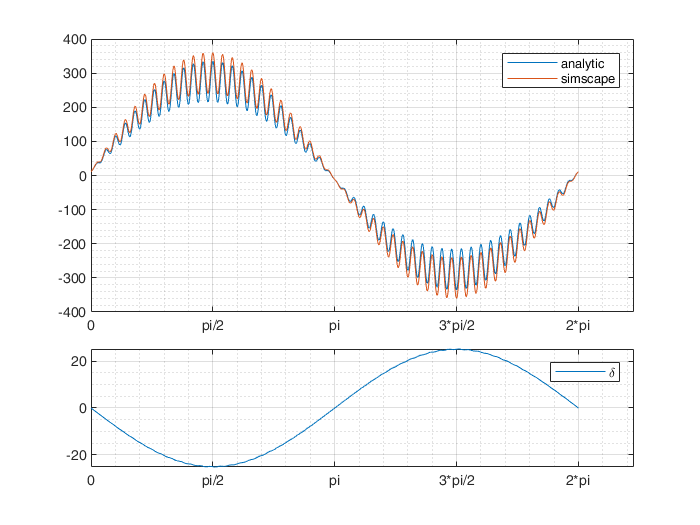

tiledlayout(3,1);
nexttile(1,[2 1]);
plot(simAngRS,[traj(2,:);simCordRS(2,:)])
setupPlot(ticks); legend('analytic','simscape');

nexttile(3);
plot(simAngRS,[traj(2,:)-simCordRS(2,:)])
setupPlot(ticks); legend('\delta');

#### z-Achse

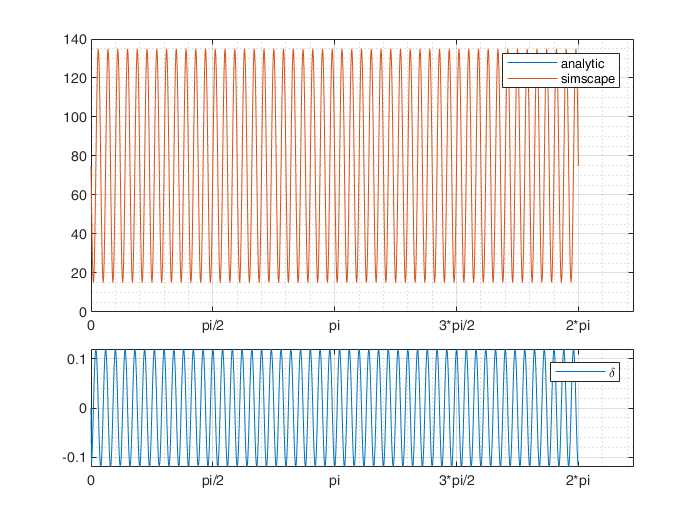

tiledlayout(3,1);
nexttile(1,[2 1]);
plot(simAngRS,[traj(3,:);simCordRS(3,:)])
setupPlot(ticks); legend('analytic','simscape');

nexttile(3);
plot(simAngRS,(traj(3,:)-simCordRS(3,:)))
setupPlot(ticks); legend('\delta');

function setupPlot(ticks)
set(gca,'XTick',ticks.range)
set(gca,'XTickLabel',ticks.chars)

grid on;
grid minor;
end